Int1 = importdata("Int1.txt");
x1 = Int1(:,1);
v1 = Int1(:,2);

Int2 = importdata("Int2.txt");
x2 = Int2(:,1);
v2 = Int2(:,2);
%


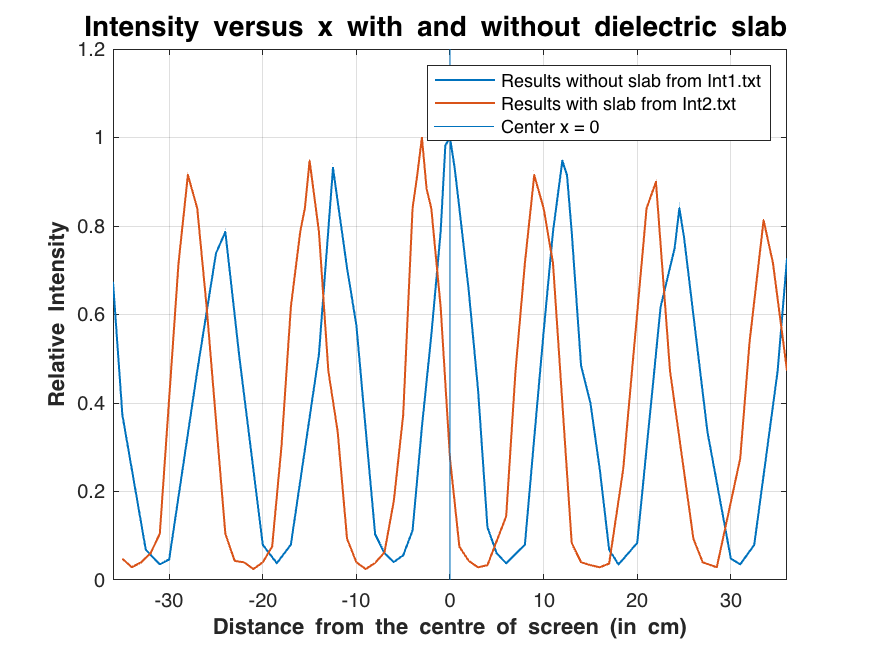

plot(x1,(v1/max(v1)).^2,LineWidth=1);
hold on;
plot(x2,(v2/max(v2)).^2,LineWidth=1);
grid on;
xlabel('{\bfDistance from the centre of screen (in cm)}')
ylabel('{\bfRelative Intensity}')

axis([-36 36 0 1.2]);

line([0 0],[0 1.2])
legend("Results without slab from Int1.txt", ...
    "Results with slab from Int2.txt", ...
    "Center x = 0")
title('{\bfIntensity versus x with and without dielectric slab  }','FontSize',14)
hold off;